**Question 3: 2D Polynomial Surface Interpolation**

**3a. Unconstrained Polynomial Surface Interpolation**

% Load the dataset
% Load the dataset
alldata= load('C:\Users\sanus\Documents\MATLAB\Final Exam\polynomial2D.mat');
alldata = dataTT{:,:};
disp(size(alldata))

       86400          11



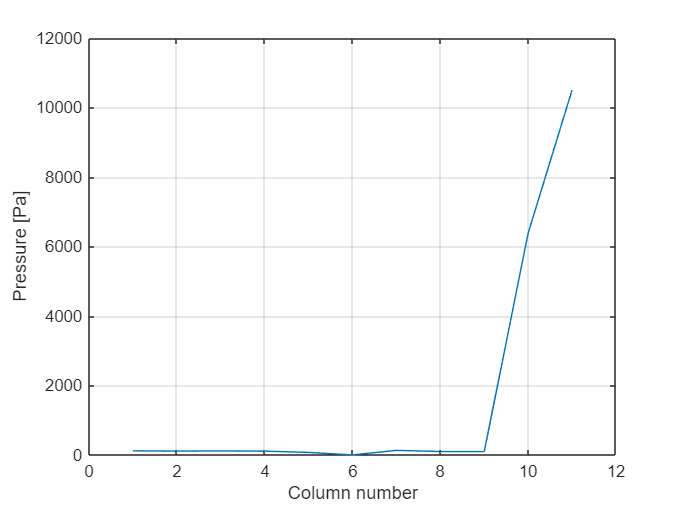

[maxVal, idx] = max(alldata);
figure;
plot(maxVal);
grid on;
xlabel('Column number');
ylabel('Pressure [Pa]');


[~, colMax] = max(maxVal);
rowMax = idx(colMax);
disp(rowMax)

       63276




rowData = alldata(rowMax, :) - alldata(2, :);
rowData = rowData./max(max(rowData));
disp(rowData)

   -0.0254    0.0068   -0.0133   -0.0423         0    0.0076   -0.0805         0   -0.0468    0.2217    1.0000



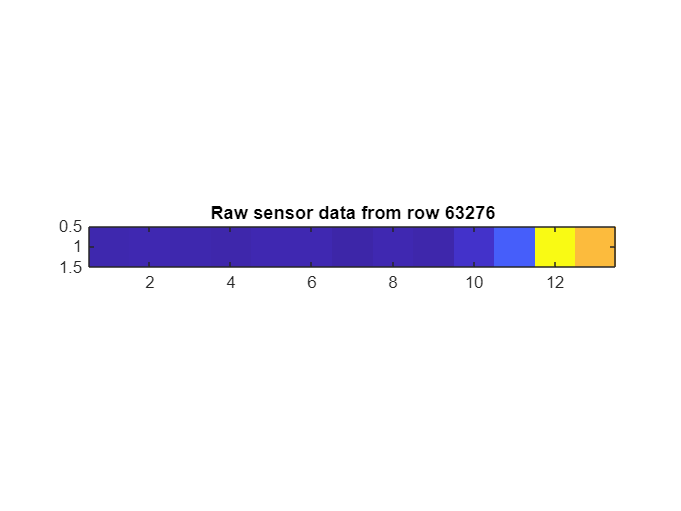


nrSensorHor = 5;
nrSensorVer = 6;
sensorData = [rowData, nrSensorVer, nrSensorHor];

figure
imagesc(sensorData);
axis image;
title(['Raw sensor data from row ', num2str(rowMax)]);


degX = size(sensorData, 2) - 1;
degY = size(sensorData, 1) - 1;
x = linspace(-1, 1, degX + 1);
y = linspace(-1, 1, degY + 1);

Vx = vander(x);
Vy = vander(y);
uncCoeffs = pinv(Vy)*sensorData*pinv(Vx');

**3b. Plot the Results**

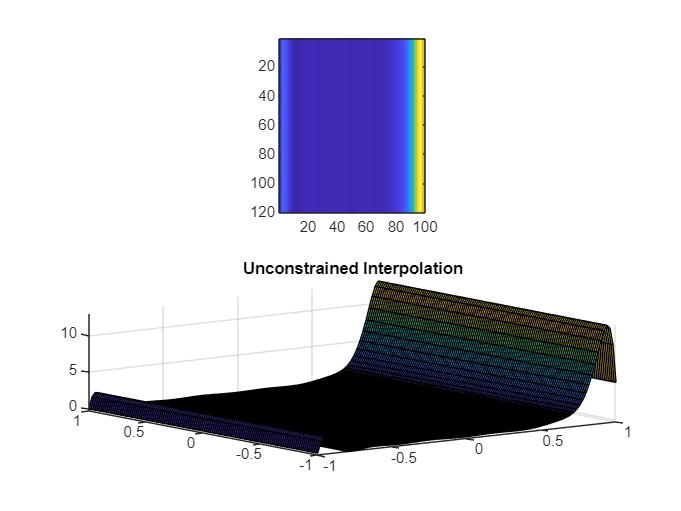

factor = 20;
xPlot = linspace(-1, 1, factor*nrSensorHor);
yPlot = linspace(-1, 1, factor*nrSensorVer);
Vxb = vander(xPlot);
Vyb = vander(yPlot);
VxPlot = Vxb(:, end-degX:end);
VyPlot = Vyb(:, end-degY:end);
%
interpSurface = VyPlot*uncCoeffs*VxPlot';

figure
subplot(2,1,1)
imagesc(interpSurface);
axis image;
subplot(2,1,2)
[xSurf, ySurf] = meshgrid(xPlot, yPlot);
surf(xSurf, ySurf, interpSurface);
title('Unconstrained Interpolation');

**3c. Explanation for Improvement**

The interpolation could be improved by:

- **Increasing the polynomial degree**: A higher-degree polynomial can capture more complex patterns in the data, but it may also lead to overfitting.

- **Using regularization**: Tikhonov regularization can help prevent overfitting by penalizing large coefficients.

- **Using spline interpolation**: Splines can provide a smoother fit, especially for noisy data, by using piecewise polynomials.